# **Figure 7**

This m-file is written according  to  the paper entitled :

 "**An Efficient Low-Complexity Method to Calculate Hybrid Beamforming Matrices for mmWave Massive MIMO Systems**" 

you can see the paper on this link:  [https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9442813](https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9442813)

## **Authors: **

**1- Jamal Beiranvand** 

    Website: 

    e-mail: Jamalbeiranvand@gmail.com

    google scholar:  [https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en](https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en)

2- **Vahid Meghdadi**

    website: [https://www.unilim.fr/pages_perso/vahid/](https://www.unilim.fr/pages_perso/vahid/) 

    e-mail: meghdadi@ensil.unilim.fr

    google scholar:  [https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en](https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en)

## Required Functions to run

All functions used in this code are in the** "Functions" **folder, described in the **"MATLAB Functions" **document.

**Note: **change  the path of **Functions** folder according its path in your PC.

Date : 02/07/2021

By Jamal Beiranvand

## Initialize

clear;
clc
warning off
%% User pannel Parameters (you may have to change some values in the "Plot" section)
addpath(genpath('C:\Users\Jamal\OneDrive\Jamal\MATLAB Code\Functions' )) % Add path of the "Functions" folder.
Nps = 8;                      % Values of Bits, it can be a vector, you can use 'inf' for infinity resolution
Txz = 12;                      % Number of the transmitter antennas on z axis
Txy = 12;                      % Number of the transmitter antennas on y axis
Rxz = 6;                       % Number of the receiver antennas on z axis
Rxy = 6;                       % Number of the receiver antennas on y axis
Ns  = 5;                       % Number of data streams
NRF = Ns;                      % Number of RF chains
Ncl =10;                       % Number of Channel clusters(Scatters)
Nray= 5;                       % Number of rays in each cluster
AngSpread = 10;       % Angle spread, standard deviation of the angles in azimuth and elevation both of Rx and Tx
SNR_dB = -10:5:30;             % Signal to noise ratio in dB
realization = 100;             % Iteration of simulation

%% Initialize Parameters
Tx  = [Txz,Txy];               % Srtucture of the transmit antanna array
Rx  = [Rxz,Rxy];               % Srtucture of the receiver antanna array 
Nt  = Txz*Txy;                 % Number of the transmit antennas
Nr  = Rxz*Rxy;                 % Number of the receive antennas
SNR = 10.^(SNR_dB./10);        
%% Allocate memory space for matrices
R_Nov=zeros(length(SNR_dB),realization);    
R_Dig=zeros(length(SNR_dB),realization);
R_FPS=zeros(length(SNR_dB),realization);

Data1=zeros(length(SNR_dB),length(Nps));
Data2=zeros(length(SNR_dB),length(Nps));
Data3=zeros(length(SNR_dB),length(Nps));


## Main Code

%% Main Code
for n=1:length(Nps)
    % Generate basis set and switches states
    [Setb,Sb]=GenUniqueSet(Nps);
    
    for reali=1:realization
        formatSpec = 'Iteration %i of %i \n';
        fprintf(formatSpec,reali,realization)
        % generate channel
        [H,At,Ar,alpha]=Channel(Tx,Rx,Ncl,'Nray',Nray,'AngSpread',AngSpread);
        
        % Full Digital beamforming
        [W_Dig,F_Dig]=DigitalBeamforming(H,Ns);
        
        % Novel Algorithm
        [WRF_Nov,WBB_Nov,FRF_Nov,FBB_Nov] = NovelAlg(H,Ns,Setb,Sb);
 
        % FPS-AltMin
         [WRF_FPS,WBB_FPS,FRF_FPS,FBB_FPS]= FPS_AltMin(H,NRF,Ns,Nps);
          for r=1:length(SNR)
             % Sihrabi Algorithm, quantize during computing
            [WDq,WRFq,VRFq,VDq]=Sohrabi_Alg(H,NRF,Ns,SNR(r),Nps);
            Vtq=VRFq*VDq;       
            Wtq=WRFq*WDq;
            R_shrb(r,reali) = log2(det(eye(Ns) +  pinv(Wtq)  * H * Vtq  * (Vtq)'  * H' * Wtq));        
            
            R_FPS(r,reali) = log2(det(eye(Ns) + SNR(r)/Ns * pinv(WRF_FPS * WBB_FPS)  * H * FRF_FPS * FBB_FPS * (FBB_FPS)' * FRF_FPS' * H' * WRF_FPS * WBB_FPS));
            R_Nov(r,reali) = log2(det(eye(Ns) + SNR(r)/Ns * pinv(WRF_Nov * WBB_Nov)  * H * FRF_Nov * FBB_Nov * (FBB_Nov)' * FRF_Nov' * H' * WRF_Nov * WBB_Nov));
            R_Dig(r,reali) = log2(det(eye(Ns) + SNR(r)/Ns * pinv(W_Dig)  * H * F_Dig  * (F_Dig)'  * H' * W_Dig));
          end
    end
    Data1(:,n)= sum((R_Dig),2)/realization;
    Data2(:,n)= sum(R_Nov,2)/realization;
    Data3(:,n)= sum(R_FPS,2)/realization;
    Data4=sum(R_shrb,2)./realization;
end

Iteration 1 of 100 
Iteration 2 of 100 
Iteration 3 of 100 
Iteration 4 of 100 
Iteration 5 of 100 
Iteration 6 of 100 
Iteration 7 of 100 
Iteration 8 of 100 
Iteration 9 of 100 
Iteration 10 of 100 
Iteration 11 of 100 
Iteration 12 of 100 
Iteration 13 of 100 
Iteration 14 of 100 
Iteration 15 of 100 
Iteration 16 of 100 
Iteration 17 of 100 
Iteration 18 of 100 
Iteration 19 of 100 
Iteration 20 of 100 
Iteration 21 of 100 
Iteration 22 of 100 
Iteration 23 of 100 
Iteration 24 of 100 
Iteration 25 of 100 
Iteration 26 of 100 
Iteration 27 of 100 
Iteration 28 of 100 
Iteration 29 of 100 
Iteration 30 of 100 
Iteration 31 of 100 
Iteration 32 of 100 
Iteration 33 of 100 
Iteration 34 of 100 
Iteration 35 of 100 
Iteration 36 of 100 
Iteration 37 of 100 
Iteration 38 of 100 
Iteration 39 of 100 
Iteration 40 of 100 
Iteration 41 of 100 
Iteration 42 of 100 
Iteration 43 of 100 
Iteration 44 of 100 
Iteration 45 of 100 
Iteration 46 of 100 
Iteration 47 of 100 
Iteration 48 of 100 
I

## Plot

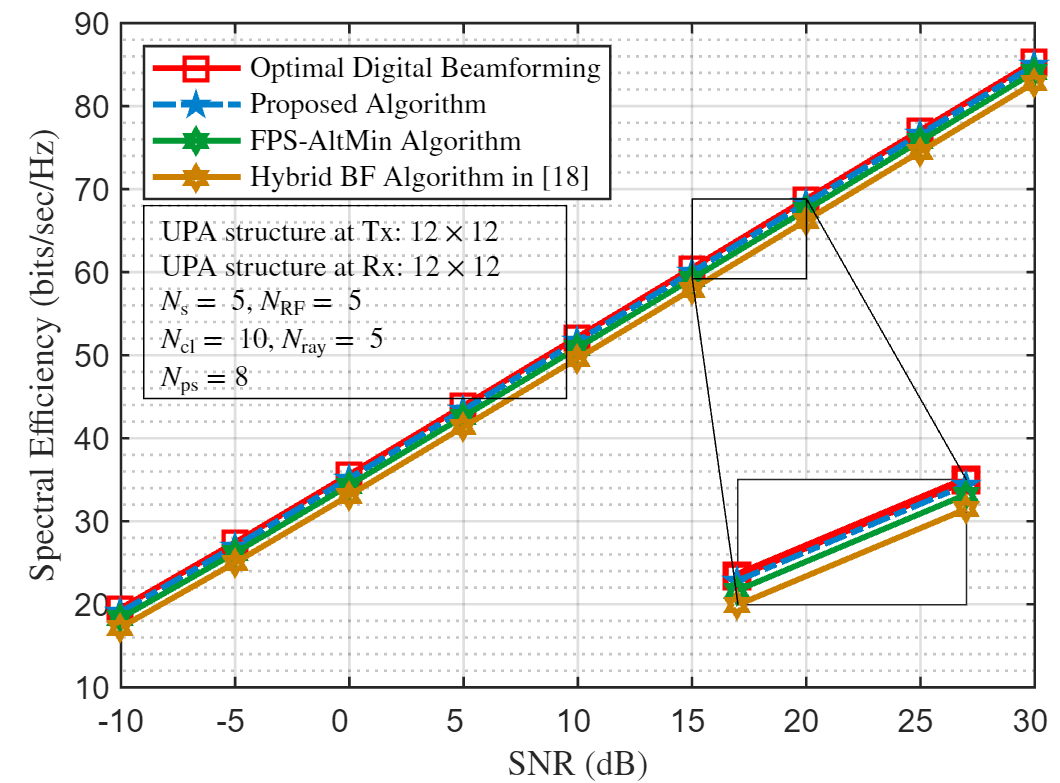

% prepare data to plot
Xaxis=SNR_dB;
%% plot 
Fig=figure;
hold on
P1=plot(Xaxis,Data1(:,1));
P2=plot(Xaxis,Data2);
P3=plot(Xaxis,Data3);
P4=plot(Xaxis,Data4);
% P5=plot(Xaxis,Data5);

Legend1='Optimal Digital Beamforming';
Legend2='Proposed Algorithm';
Legend3=('FPS-AltMin Algorithm');
 Legend4='Hybrid BF Algorithm in [18]';
% Legend5='PE-AltMin Algorithm';
% Legend3=('Data1 $N_t=144$, $Nr=36$');

% P1 properties
set(P1,'LineStyle','-');           % '-' , '--' , ':' , '-.' , 'none'
set(P1,'Marker','s');       % 'o' , '+'  , '*' , 'x' ,'s' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram', 'none'
set(P1,'LineWidth',2);
set(P1,'Color','r');
set(P1,'MarkerSize',10);
P1_group= hggroup;set(P1,'Parent',P1_group);
set(get(get(P1_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on'); 
% P1.MarkerIndices =[ 1 6];

% P2 properties
set(P2,'LineStyle','-.');           % '-' , '--' , ':' , '-.'
set(P2,'Marker','pentagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P2,'LineWidth',2);
set(P2,'Color',[0 .5 .8]);
set(P2,'MarkerSize',5);
P2_group= hggroup;set(P2,'Parent',P2_group);
set(get(get(P2_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');

% P2 properties
set(P3,'LineStyle','-');           % '-' , '--' , ':' , '-.'
set(P3,'Marker','hexagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P3,'LineWidth',2);
set(P3,'Color',[0 .6 .2]);
set(P3,'MarkerSize',7);
P3_group= hggroup;set(P3,'Parent',P3_group);
set(get(get(P3_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 
% % P2 properties
set(P4,'LineStyle','-');           % '-' , '--' , ':' , '-.'
set(P4,'Marker','hexagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P4,'LineWidth',2);
set(P4,'Color',[.8 .5 0]);
set(P4,'MarkerSize',7);
P4_group= hggroup;set(P4,'Parent',P4_group);
set(get(get(P4_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 
% % P2 properties
% set(P5,'LineStyle','--');           % '-' , '--' , ':' , '-.'
% set(P5,'Marker','x');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
% set(P5,'LineWidth',2);
% set(P5,'Color',[.8 .5 .5]);
% set(P5,'MarkerSize',7);
% P5_group= hggroup;set(P5,'Parent',P5_group);
% set(get(get(P5_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 

lgd=legend(Legend1,Legend2,Legend3,Legend4);
% Axes Properties 
ax=gca;
ax.XLim = [min(Xaxis) max(Xaxis)];
% ax.YLim = [5 40];
ax.XTick = Xaxis;
ax.XTickLabel=Xaxis;
ax.XLabel.String='SNR (dB)';
ax.YLabel.String='Spectral Efficiency (bits/sec/Hz)';
ax.XGrid='on';
ax.YGrid='on';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
ax.YLabel.Interpreter='latex';
ax.XLabel.Interpreter='latex';
ax.FontSize = 11;
ax.LineWidth = .9;
ax.Box='on';

% Legend Properties %
lgd.Location= 'northwest'; %%
lgd.Box='on';
lgd.LineWidth=.9;
lgd.Interpreter='latex';
lgd.FontSize = 10;
% 
% Figure Properties
ax.Units='centimeters';
ax.Position = [ax.TightInset(1)+ax.TightInset(3) ax.TightInset(2) 11 8];
Fig.Units='centimeters';
Fig.Position = [10 5 (ax.TightInset(1)+ 2*ax.TightInset(3)+ ax.Position(3) ) (ax.TightInset(2)+ ax.TightInset(4)+ ax.Position(4))];

%  Creat notation 
Not1=annotation('textbox');
X_points=[-9 9.5];
Y_points=[ .56*(diff(ax.YLim)) .85*(diff(ax.YLim))];
str1=['UPA structure at Tx: ',num2str(Tx(1)),'$\times$',num2str(Tx(2))];
str2=['UPA structure at Rx: ',num2str(Tx(1)),'$\times$',num2str(Tx(2))];
str3=['$N_{\mathrm{s}}=$ ',num2str(Ns),',  $N_{\mathrm{RF}}=$ ',num2str(NRF)];
str4=['$N_{\mathrm{cl}}=$ ',num2str(Ncl),',  $N_{\mathrm{ray}}=$ ',num2str(Nray)];
str5=['$N_{\mathrm{ps}}=$',num2str(Nps)];
Not1.String={str1,str2,str3,str4, str5};
Not1.FontSize = 10;
Not1.Interpreter='latex';
Not1.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Not1.Position=[x_begin y_begin  x_End y_End];
% % % % 
x1=6;
x2=7;

Not1=annotation('textbox');
X_points=[(Xaxis(x1)) (Xaxis(x2))];
Y_points=[abs(Data3(x1)) abs(Data1(x2))];
Not1.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Not1.Position=[x_begin y_begin  x_End y_End];

%%
X_points_Fig=[17 27];
Y_points_Fig=[20 35];
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points_Fig(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points_Fig(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points_Fig(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points_Fig(2)*Dy)-y_begin;
NewFig=[x_begin y_begin  x_End y_End];

Textarrow1=annotation('line');
X_points=[(Xaxis(x1)) X_points_Fig(1)];
Y_points=[abs(Data3(x1)) Y_points_Fig(1)];
Textarrow1.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Textarrow1.Position=[x_begin y_begin  x_End y_End];

Textarrow2=annotation('line');
X_points=[(Xaxis(x2)) X_points_Fig(2)];
Y_points=[abs(Data1(x2)) Y_points_Fig(2)];
Textarrow2.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Textarrow2.Position=[x_begin y_begin  x_End y_End];
%% Data on sub figure
axes ('Units','centimeters','Position',NewFig)
hold on
P1=plot(Xaxis(x1:x2),Data1(x1:x2));
P2=plot(Xaxis(x1:x2),Data2(x1:x2));
P3=plot(Xaxis(x1:x2),Data3(x1:x2));
P4=plot(Xaxis(x1:x2),Data4(x1:x2));
% P5=plot(Xaxis,Data5);

% P1 properties
set(P1,'LineStyle','-');           % '-' , '--' , ':' , '-.' , 'none'
set(P1,'Marker','s');       % 'o' , '+'  , '*' , 'x' ,'s' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram', 'none'
set(P1,'LineWidth',3);
set(P1,'Color','r');
set(P1,'MarkerSize',10);
P1_group= hggroup;set(P1,'Parent',P1_group);
set(get(get(P1_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on'); 
% P1.MarkerIndices =[ 1 6];

% P2 properties
set(P2,'LineStyle','-.');           % '-' , '--' , ':' , '-.'
set(P2,'Marker','pentagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P2,'LineWidth',2);
set(P2,'Color',[0 .5 .8]);
set(P2,'MarkerSize',5);
P2_group= hggroup;set(P2,'Parent',P2_group);
set(get(get(P2_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');

% P2 properties
set(P3,'LineStyle','-');           % '-' , '--' , ':' , '-.'
set(P3,'Marker','hexagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P3,'LineWidth',2);
set(P3,'Color',[0 .6 .2]);
set(P3,'MarkerSize',7);
P3_group= hggroup;set(P3,'Parent',P3_group);
set(get(get(P3_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');

set(P4,'LineStyle','-');           % '-' , '--' , ':' , '-.'
set(P4,'Marker','hexagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P4,'LineWidth',2);
set(P4,'Color',[.8 .5 0]);
set(P4,'MarkerSize',7);
P4_group= hggroup;set(P4,'Parent',P4_group);
set(get(get(P4_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');


 ax=gca;
ax.XLim = [min(Xaxis(x1)) max(Xaxis(x2))];
ax.YLim = [min(abs(Data4(x1))) max(abs(Data1(x2)))];
ax.XTick=[];
ax.YTick=[];
ax.Box='on';

%  ax.Visible='off';


